Algotirmo A*

clc; clear; close all
% ******************** + Parametros del sistema  + ********************
 % Tiempo de muestreo
T = 0.01;                
% modelo del sistema en su funcion de transferencia
s = tf('s');
G = 4.228 / ((s+0.5) * (s^2 + 1.64*s + 8.456))     % G1 de ejemplo

G =
 
               4.228
  --------------------------------
  s^3 + 2.14 s^2 + 9.276 s + 4.228
 
Continuous-time transfer function.



%G = 27 / ((s+1)*(s+3)^3);                          % G2 de ejemplo
%G = exp(-0.5*s)/((s+1)^2)                          % G3 de ejemplo

% modelo del sisteam en espacio de estados
H = c2d(G,T);
[num,den] = tfdata(H,'v');
[A, B, C, D] = tf2ss(num,den)

A =     2.9779   -2.9567    0.9788
    1.0000         0         0
         0    1.0000         0


B =      1
     0
     0


C = 	1.0e+-5 *

    0.0701    0.2788    0.0693


D = 0


% *******************************  ZN  **************************************
Ku = 3.665;
Tu = 2.06;
%Ku = 5.12;
%Tu = 2.06;
%Ku = 4.68;
%Tu = 3.28;
% ********************* + Parametros del controlador + **********************
Kp = 0.6 * Ku

Kp = 2.1990

Ki = 0.6 * Ku * 2 / Tu ;  % Ki = (Kp/Ti) ; Ti = Tu/2
Kd = 0.6 * Ku * Tu /  8;  % Kd = (Kp*Td) ; Td = Tu/8
Ti = Kp/Ki

Ti = 1.0300

Td = Kd/Kp

Td = 0.2575

% ********************* + Definicion de la funciond de costo + *************
Gains = [Kp Ki Kd] ;   

Kpmin = 0.533 * Kp; % 0.32 * Ku;
Kpmax =    1  * Kp; % 0.60 * Ku;
Kdmin = 1.067 * Kd; % 0.08 * Ku * Tu;
Kdmax =     2 * Kd; % 0.15 * Ku * Tu;
Kimin =  0.01 * Ki;
Kimax =  0.85 * Ki;

range_gains = [Kpmin Kpmax Kdmin Kdmax Kimin Kimax];


n_values1 = 5;
n_values2 = 6;
n_values3 = 10;

Kp_values = linspace(Kpmin,Kpmax,n_values1);
Kd_values = linspace(Kdmin,Kdmax,n_values2);
Ki_values = linspace(Kimin,Kimax,n_values3);

space = zeros(length(Kp_values) ,length(Kd_values),length(Ki_values));
[dim1, dim2, dim3] = size(space);
ID = GenerateID(dim1, dim2, dim3);

X1 = find( Kp_values == Kp)

X1 = 5

Y1 = find( abs(Kd_values-Kd)<0.1,1)

Y1 = 1

Z1 = find( abs(Ki_values-Ki)<0.4,1)

Z1 = 10

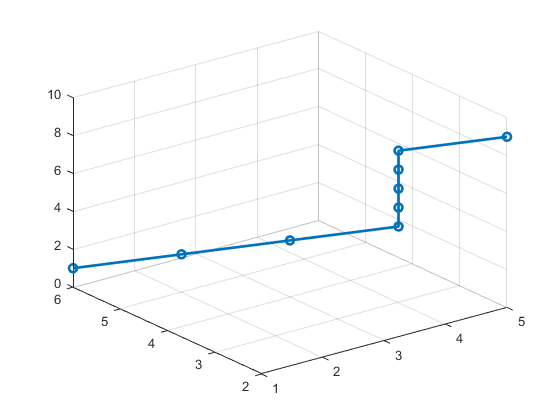

Kp = 2.1990

Ki = 0.8184

Kd = 1.1325


if (isempty(X1)||isempty(Y1)||isempty(Z1))
    X1=1;Y1=1;Z1=1;
end

X2 = randi(n_values1);
Y2 = randi(n_values2);
Z2 = randi(n_values3);

X2 = -1;
Y2 = -1;
Z2 = -1;

% ******************** PID ***************************
ref = 1;
[y1,t1] = PIDcontrol(G,ref,Gains,T);
%***************************************************************************************************
funtion_H = @(Gains)CalculeCost(G,ref,Gains,T);    % Funcion Objetivo

[Kp, Ki, Kd] = Aestrella(space, X1, Y1 , Z1 ,X2, Y2, Z2 ,ID,Kp_values,Kd_values,Ki_values,funtion_H)

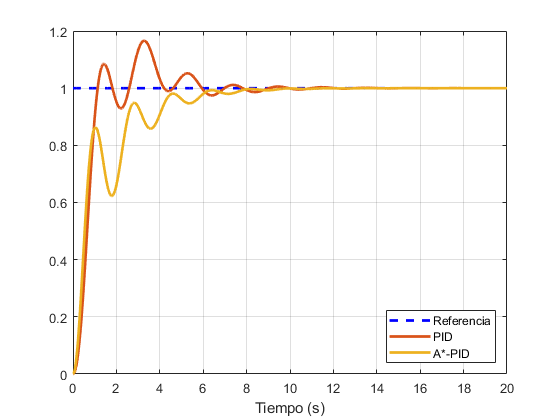


[y2,t2] = PIDcontrol(G,ref,[Kp, Ki, Kd],T);

figure(1)
plot(t1, ref*ones(1,length(t1)),'b--',t1,y1,t2,y2, 'LineWidth', 2); grid on
xlabel('Tiempo (s)')
legend({'Referencia', 'PID','A*-PID'},'Location','southeast')

function  [Kp, Ki, Kd] = Aestrella(space, X1, Y1 , Z1 ,X2, Y2, Z2 ,ID,Kp_values,Kd_values,Ki_values,funtion_H)

    [dim1,dim2,dim3] = size(space);       % espacio de busqueda
    
    F = nan*ones(dim1,dim2,dim3);         % F = G + H
    G = zeros(dim1,dim2,dim3);            % Costo
    H = nan*ones(dim1,dim2,dim3);         % Heurística
    
    y_cifras = 10^length(num2str(dim1));
    z_cifras = 10^(length(num2str(dim1)) + length(num2str(dim2)));

    padre= zeros(dim1,dim2,dim3);               % nodos padres idica el punto de donde provino
    Lista_a = ID(X1,Y1,Z1);                     % lista abierta : contine los pixel que se van ha visitar cuando se busca la ruta
    Lista_aF = nan*ones(dim1*dim2*dim3,1);      % lista  F (costos totales)
    Lista_aF(1)  = ID(X1,Y1,Z1);
    Lista_c = [];                     % lista cerrada : contiene los pixel de los cuales ya se verifico sus distancias vecinas   
    
    fin = 0;                              % bandera de salida
    G_X1 = X1; G_Y1 = Y1; G_Z1 = Z1;      % guarda el valor del punto inicial

    
    while fin == 0    % mientras no encuntre el punto final
        for z = Z1-1:Z1+1
            for  y = Y1-1 : Y1+1     % busca en los pixeles vecinos la que se genera F con menor costo
                for x = X1-1 : X1+1    
                    if x <= dim1 && y <= dim2 && z <= dim3  && x >= 1 && y >= 1 &&  z >= 1     
                        if space(x,y,z) == 0 && isempty(find(Lista_c == ID(x,y,z), 1)) == 1
                            pos_a = find(Lista_a == ID(x,y,z),1); 
                            if isempty(pos_a) == 1 % si se tiene nuevos vecinos
                                % calculaa el costo G y la heuristica H
                                Gains = [Kp_values(x) Ki_values(z) Kd_values(y)];
                                H(x,y,z)  = funtion_H(Gains);
                                G(x,y,z) = G(X1,Y1,Z1)+ sqrt((x-X1)^2+(y-Y1)^2+(z-Z1)^2); 
                                F(x,y,z) = G(x,y,z) + H(x,y,z);
                                % nodo de donde provino 
                                padre(x,y,z) = ID(X1,Y1,Z1);
                                % se agrega a la lista de pixel de vecinos conocidos
                                Lista_a = cat(1,Lista_a,ID(x,y,z)) ;
                                Lista_aF(length(Lista_a)) = F(x,y,z);
                            else 
                              G_a = G(X1,Y1,Z1)+ sqrt((x-X1)^2+(y-Y1)^2)+(z-Z1)^2;
                              if G_a < G(x,y,z)
                                 G(x,y,z) = G_a;
                                 padre(x,y,z) = ID(X1,Y1,Z1);    % si el gasto es menor 
                                 F(x,y,z) = G(x,y,z) + H(x,y,z); % coloca su nuevo padre
                                 Lista_aF(pos_a) = F(x,y,z);     % y costo 
                              end
                            end
                        end
                    end
                end
            end
        end
        ID_XYZ = find(Lista_aF == min(Lista_aF),1);    % busca su indentificador
        if  isempty(ID_XYZ) ~= 1                       % si se encontro la posicion del valor minimo 
            ZYX = Lista_a(ID_XYZ);                     % determina las cordenadas
            Z1 = fix(ZYX / z_cifras);      
            YX = ZYX - Z1 * z_cifras;
            Y1 = fix( YX / y_cifras);
            X1 =  YX - Y1 * y_cifras;
            % quita el elemento encontrado de la lista de vecinos
            % abiertos y lo coloca en los cerrados
            Lista_c = cat(1,Lista_c,ID(X1,Y1,Z1));   
            Lista_a  = [Lista_a(1:ID_XYZ-1,1); Lista_a(ID_XYZ+1:end,1)];
            Lista_aF  = [Lista_aF(1:ID_XYZ-1,1); Lista_aF(ID_XYZ+1:end,1)];
        end
        % si llega al destino o si se ha analziado todos los valores de espacio de busqueda
        % termina el bucle 
        if ((X1 == X2 && Y1 == Y2 && Z1 == Z2)||isempty(ID_XYZ) == 1)        
            fin = 1 ;
            [x_min, yz_min] = find( H == min(H,[],'all'),1);
            y_min = (mod(yz_min-1,dim2)+1);
            z_min = fix((yz_min-1)/ dim2)+1;
            Kp = Kp_values(x_min) ;
            Kd = Kd_values(y_min);
            Ki = Ki_values(z_min);
        end
    end
    ruta = ID(x_min,y_min,z_min);       % para buscar la ruta comenzamos con el punto final
    x_i = [];
    y_i = [];
    z_i = [];
 
    while X1 ~= G_X1 ||  G_Y1 ~= Y1 || G_Z1 ~= Z1
        x = X1 ; y = Y1; z  = Z1;   
        ruta = cat(1,ruta,padre(x,y,z)) ; % busca en la matriz de padres de donde provino cada valor
        ZYX = padre(x,y,z);
        Z1 = fix(ZYX / z_cifras);      
        YX = ZYX - Z1 * z_cifras;
        Y1 = fix( YX / y_cifras);
        X1 =  YX - Y1 * y_cifras;
        x_i = cat(1,x_i,x) ;
        y_i= cat(1,y_i,y) ;
        z_i = cat(1,z_i,z) ;
    end
    figure(1)
    %surf(H) ; hold on 
    plot3(x_i,y_i,z_i,'o-','linewidth',2); grid on
    hold off
end

function [y,t]  = PIDcontrol(G,ref,Gains,dt)
    Kp = Gains(1);
    Ki = Gains(2);
    Kd = Gains(3);
    
    s = tf('s');
    Gc = Kp + Ki/s + Kd*s/(1+.001*s);
    Loop = series(Gc,G);
    ClosedLoop = feedback(Loop,1);
    
    t = 0:dt:20;
    [y,t] = step(ClosedLoop,t);
    y = ref*y;
end

function J = CalculeCost(G,ref,Gains ,T)
    [y,~] = PIDcontrol(G,ref,Gains,T);
    select_costF = 2;
    J = CostFunction(y',ref,select_costF,T);    % Funcion Objetivo
end

function  ID = GenerateID(dim1,dim2,dim3)
    ID = zeros(dim1,dim2,dim3);% matriz de ceros  
    x_cifras = 1;
    y_cifras = 10^length(num2str(dim1));
    z_cifras = 10^(length(num2str(dim1)) + length(num2str(dim2)));

        for i = 1:dim1        % para cada fila de la matriz
            for j = 1:dim2    % para cada columna de la matriz
                for k = 1:dim3
                    % el numero de identifación es una transfomacion linal 
                    % de a fila i columna j 
                       ID(i,j,k) = i*x_cifras + j * y_cifras + k * z_cifras;  
                end
            end 
        end
end